# Planificadores de tareas en tiempo real

El problema de planificación es una problema de administración de recursos, por tanto, de optimización combinatoria. Decisiones de planificador: decisión de ejecutar una tarea

- Asignación: que procesador ejecutará la tarea.

- Ordenamiento(asignación): en que orden cada procesador.

- Puntualidad(asignación): el tiempo en el cual se ejecuta una tarea. Esto es importantisimo en sistemas en tiempo real.

Las asignaciones pueden ser distintas categorías 

    Off-line VS Online

        Off-line: La planificaciones de tareas sucede en tiempo de diseño.

        Online: La planificación sucede en tiempo de ejecución.

             Estáticos VS Dinámicos

                   Estáticos: Las decisiones se basan en parámetros invariantes en el tiempo.    (Ejemplo: RM)   

                        Apropiativos (Preemtive): Una tarea puede ser interrumpida por una tarea de mayor prioridad.

                        No apropiativos: Tarea que inicia su ejecución debe concluida.

            Dinámicos: Las decisiones se basan en parámetros variantes en el tiempo.          (Ejemplo EDF)

                        Apropiativos

                        No apropiativos: 

            Óptimos VS Heurísticos

                Óptimos: se minimiza una función de costo definida sobre el conjunto de tareas

         Si no existe una función de costo, la planificación se dice que es factible 

                Heurísticos: existe una función heurística (aproximación), para tratar de ser una planificación óptima (asintótico)

Para empezar a hablar de los planificadores en tiempo real debemos comenzar con la definición del modelo de tareas.

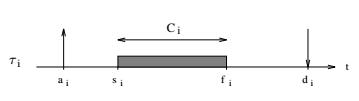

- $t$ es el tiempo en el eje horizontal

- $\tau {\;}_{i\;}$ es conjunto de tareas, $i$ la i-esima instancia de la tarea

- $a_{i\;}$es el tiempo de arribo de la i-esima instancia de la tarea a la cola del planificador

- $s_i$ es el tiempo de inicio de ejecución de la i-esima instancia de la tarea

- $C_{i\;}$es el tiempo de completitud de la i-esima instancia de la tarea

-     ${\textrm{WCET}}_{i\;}$(Worst Case Execution Time) el peor caso del tiempo de completitud

-         Depende 

-                 Arquitectura

-                     Multinucleo?              

-                    Acceso a memoria?

-                 Lenguaje de programación

-                     Compilado/Interpretado?

-                 Algoritmo         

-                     Paralelizable?        

- $f_{i\;}$ es el tiempo de fin de ejecución de la tarea de la i-esima instancia de la tarea

- $d_{i\;}$es el tiempo de fin de plazo de la i-esima instancia de la tarea

- $h$ es un periodo de la i-esima instancia de la tarea

-         La fisica del sistema

-     
$$a_i =h\cdot \;i$$


-     
$$d_i =h\cdot \left(i+1\right)=a_{i+1}$$


Ejemplo: de una tarea o proyecto

- $a_i$ - 23 de febrero     

- $d_{i\;}$- 9 de marzo

- $C_{i\;}$- 3 días

-     $s_{i,0\;}$- 1 de marzo

-     $c_{i,0}$ - 1 días

-     $d_{i,0}$ - 2 marzo

-     $s_{i,1}$ - 3 de marzo

-     $c_{i,1}$ - 2 días

-     $d_{i,1}$ - 5 marzo

## Definición de las tareas

clc;
clear all;

T_min = 1e-3;
T_max = T_min*100;

t = 0:T_min:T_max;

% Tarea 1 es periodica.
P(1) = 5*T_min;
C(1) = 2*T_min;
c(1) = 0;
ready(1) = false;
terminated(1) = false;
standby(1) = false;
running(1) = false;

%Tarea 2 es perdioca
P(2) = 4*T_min;
C(2) = 1*T_min;
c(2) = 0;
ready(2) = false;
terminated(2) = false;
standby(2) = false;
running(2) = false; 

%Tarea 3 es periodica
P(3) = 8*T_min;
C(3) = 3*T_min;
c(3) = 0;
ready(3) = false;
terminated(3) = false;
standby(3) = false;
running(3) = false;

### Rate Monotonic (RM)

Idx = 0;
tau = [0,0,0];

for i = 1:30

`arrived `define las tareas que han arribado, es decir, la tareas periodicas pueden estar disponibles de nuevo, por ejemplo, 

t1 = 0, 5, 10, 15 ... 5n;

t2 = 0, 4, 8, 12 ... 4n;

t3 = 0, 8, 16, 24, ... 8n;

    arrived = mod(t(i), P) == 0;          

`ready` define las tareas que estan listas en la cola de tareas, depende de las tareas que han arribado


$$\textrm{ready}\left(t\right):=f\left(\textrm{ready}\left(t-1\right),\;\textrm{arrived}\left(t\right)\right):=\textrm{ready}\left(t-1\right)\;\vee \;\textrm{arrived}\left(t\right)$$


Ejemplo: si $\textrm{arrived}\left(t\right)=\left\lbrack 0,1,0\right\rbrack \;$y $\textrm{ready}\left(t-1\right)=\left\lbrack 1,0,0\right\rbrack$, $\textrm{ready}\left(t\right)=\left\lbrack 1,1,0\right\rbrack$, es decir, que $t_{2\;}$arribo y ahora se acomoda en la cola de tareas listas a elegir.

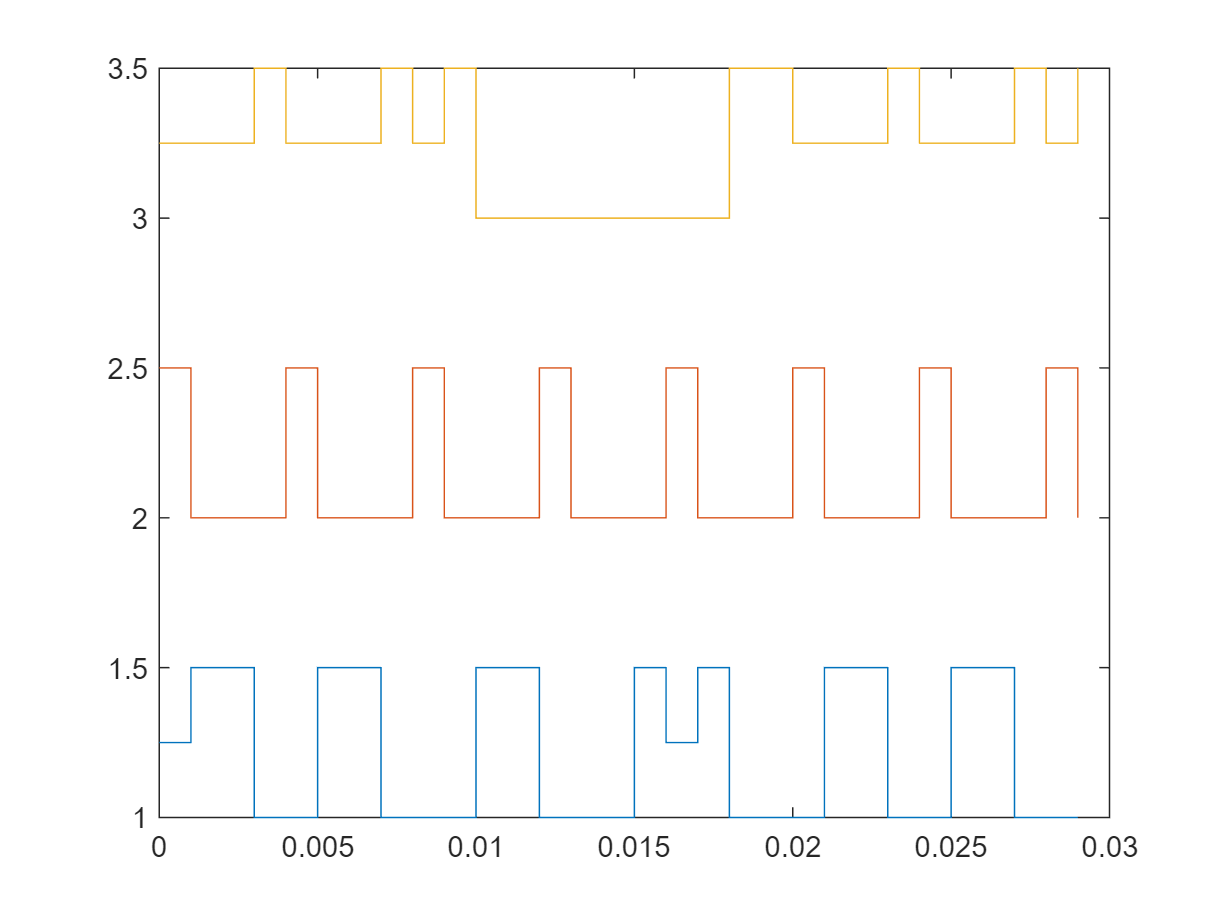

    ready = or(arrived, ready); 

`terminated `define las tareas que ya concluyeron, pero se desmarca cuando una nueva tarea ha arrivado


$$\mathrm{teminated}\left(t\right):=f\left(\mathrm{terminated}\left(t-1\right),\mathrm{arrived}\left(t\right)\right):=\bar{\mathrm{arrived}\left(t\right)} \wedge \mathrm{terminated}\left(t-1\right)$$


Ejemplo1: si $\textrm{terminated}\left(t-1\right)=\left\lbrack 1,0,0\right\rbrack ;\;\textrm{arrived}\left(t\right)=\left\lbrack 1,0,0\right\rbrack ;~\textrm{arrived}\left(t\right)=\left\lbrack 0,1,1\right\rbrack ;\;\textrm{terminated}\left(t\right)=\left\lbrack 0,0,0\right\rbrack$

Ejemplo2: si $\begin{array}{l}
\textrm{terminated}\left(t-1\right)=\left\lbrack 1,0,0\right\rbrack ;\;\textrm{arrived}\left(t\right)=\left\lbrack 1,1,0\right\rbrack ;\textrm{terminated}\left(t\right)=\left\lbrack 0,0,0\right\rbrack \\
\textrm{standby}\left(t-1\right)=\left\lbrack X,1,X\right\rbrack ;\textrm{running}\left(t-1\right)=\left\lbrack X,1,X\right\rbrack \;\;\textrm{Ya}\;\textrm{crasheo}
\end{array}$

     terminated = and(~arrived,terminated);    

Se tiene elegir que la tarea que este en la cola y tenga la mayor proridad, es decir, con menor periodo para RM

    Per = min(P(ready));   %P = [5,4,8];    P(ready) = P([1,1,0]) = [5,4]   Per = min(P(ready)) = [4, 5]
    if(~isempty(Per))
        [Aux, IdxAux] = max(P == Per);
    else
        IdxAux = 0;
    end
    

$\textrm{IdxAux}\left(t\right)\;$va funcionar como $\mathrm{Idx}$(t);  IdxAux(t) = Idx(t)

De lo anterior se pueden tener varios casos:

- $\mathrm{Idx}\left(t-1\right)=0\;\vee \;\mathrm{Idx}\left(t\right)=\phi$, es decir, la cola esta libre

- $\mathrm{Idx}\left(t\right)=\mathrm{Idx}\left(t-1\right)$, es decir, no hay cambio en la tarea a procesar o elegir

- $\mathrm{Idx}\left(t\right)\not= \mathrm{Idx}\left(t-1\right)$, es decir, se elige una nueva tarea

-     $\textrm{Idx}\left(t-1\right)\not= 0$  Esto requiere apropiacion

-          La tarea a elegir se habilita en running ${\textrm{running}}_{\textrm{Idx}\left(t\right)} :=\min_{\textrm{ready}\left(t\right)} \left(P\right),\;$${\textrm{standby}}_{\textrm{Idx}\left(t\right)} :=\textrm{false}$;

-          La tarea habilitada anteiormente se tiene que poner en standby ${\textrm{standby}}_{\textrm{Idx}\left(t-1\right)} :=\textrm{true}$,${\textrm{running}}_{\textrm{Idx}\left(t-1\right)} :=\textrm{false}$

-     $\mathrm{Idx}\left(t-1\right)=0$ No requiere apropiación

-         La tarea a elegir se habilita en running ${\textrm{running}}_{\textrm{Idx}\left(t\right)} :=\min_{\textrm{ready}\left(t\right)} \left(P\right),\;$${\textrm{standby}}_{\textrm{Idx}\left(t\right)} :=\textrm{false}$;

    if t(i) == 0
        standby = [true, true, true];
    end
    if (isempty(IdxAux))
        continue;
    elseif (Idx(1) == IdxAux(1))
        Idx(1) = IdxAux(1);
    elseif (Idx(1) ~= IdxAux(1))
        if (Idx(1) ~= 0)    %
            running(Idx(1)) = false;          
            if (terminated(Idx(1)))
                standby(Idx(1)) = false;
            else
                standby(Idx(1)) = true;
            end
        end                
        if(IdxAux(1) ~= 0)
            running(IdxAux(1)) = true;        standby(IdxAux(1)) = false;
        end        
        Idx(1) = IdxAux(1);
    end
    
    tau(i,1) = 1 + 0.25*standby(1) + 0.5*running(1);
    tau(i,2) = 2 + 0.25*standby(2) + 0.5*running(2);
    tau(i,3) = 3 + 0.25*standby(3) + 0.5*running(3);

    if i >= 2
        figure(1);
        stairs(t(1:i), tau)
%         stairs(t(1:i), tau(:,1), t(1:i), tau(:,2), t(1:1), tau(:,3));
    end
   
    if(Idx(1) ~= 0)
        c(Idx(1)) = c(Idx(1)) + T_min;
        

Cuando se ha terminado de completar una tarea, se tienen que actualizar las variables `terminated` y `ready`. Dado que al concluir, la tarea yo tiene que estar en la cola de tareas. 


$$\begin{array}{l}
{\textrm{terminated}}_{\textrm{Idx}\left(t\right)} :=c_{\textrm{Idx}\left(t\right)} =C_{\textrm{Idx}} ;\\
{\textrm{ready}}_{\textrm{Idx}\left(t\right)} :=\bar{\;\left(c_{\textrm{Idx}\left(t\right)} =C_{\textrm{Idx}} \right)} 
\end{array}$$


        if (c(Idx(1)) == C(Idx(1)) )
            terminated(Idx(1)) = true;
            standby(Idx(1)) = false;
            ready(Idx(1)) = false;
            running(Idx(1)) = false;
            c(Idx(1)) = 0;
        end
    end
end
% figure();
% stairs(t(1:i), tau)    
% subplot(1,2,1);
% step(t(1:30), tau(:,1), t(1:30), tau(:,2), t(1:30), tau(:,3));
% subplot(1,2,2); plot(t(:), sel(:,1), t(:), sel(:,2), t(:), sel(:,3));

## Earliest Deadline First (EDF)

Idx = 0;
tau = [0,0,0];

for i = 1:30

`arrived `define las tareas que han arribado, es decir, la tareas periodicas pueden estar disponibles de nuevo, por ejemplo, 

t1 = 0, 5, 10, 15 ... 5n;

t2 = 0, 4, 8, 12 ... 4n;

t3 = 0, 8, 16, 24, ... 8n;

    arrived = mod(t(i), P) == 0;          

`ready` define las tareas que estan listas en la cola de tareas, depende de las tareas que han arribado


$$\textrm{ready}\left(t\right):=f\left(\textrm{ready}\left(t-1\right),\;\textrm{arrived}\left(t\right)\right):=\textrm{ready}\left(t-1\right)\;\vee \;\textrm{arrived}\left(t\right)$$


Ejemplo: si $\textrm{arrived}\left(t\right)=\left\lbrack 0,1,0\right\rbrack \;$y $\textrm{ready}\left(t-1\right)=\left\lbrack 1,0,0\right\rbrack$, $\textrm{ready}\left(t\right)=\left\lbrack 1,1,0\right\rbrack$, es decir, que $t_{2\;}$arribo y ahora se acomoda en la cola de tareas listas a elegir.

    ready = or(arrived, ready); 

`terminated `define las tareas que ya concluyeron, pero se desmarca cuando una nueva tarea ha arrivado


$$\textrm{teminated}\left(t\right):=f\left(\textrm{terminated}\left(t-1\right),\textrm{arrived}\left(t\right)\right):=\bar{\textrm{arrived}\left(t\right)} \wedge \textrm{terminated}\left(t-1\right)$$


Ejemplo1: si $\textrm{terminated}\left(t-1\right)=\left\lbrack 1,0,0\right\rbrack ;\;\textrm{arrived}\left(t\right)=\left\lbrack 1,0,0\right\rbrack ;~\textrm{arrived}\left(t\right)=\left\lbrack 0,1,1\right\rbrack ;\;\textrm{terminated}\left(t\right)=\left\lbrack 0,0,0\right\rbrack$

Ejemplo2: si $\begin{array}{l}
\textrm{terminated}\left(t-1\right)=\left\lbrack 1,0,0\right\rbrack ;\;\textrm{arrived}\left(t\right)=\left\lbrack 1,1,0\right\rbrack ;\textrm{terminated}\left(t\right)=\left\lbrack 0,\right\rbrack \\
\textrm{standby}\left(t-1\right)=\left\lbrack X,1,X\right\rbrack ;\textrm{running}\left(t-1\right)=\left\lbrack X,1,X\right\rbrack \;\;\textrm{Ya}\;\textrm{crasheo}
\end{array}$

     terminated = and(~arrived,terminated);    

Se tiene elegir que la tarea que este en la cola y tenga la mayor proridad, es decir, aquella tarea cuyo fin de plazo sea mas próximo EDF


$$\begin{array}{l}
\textrm{Idx}\left(t\right)=\min_{i\;} \left(D_{i\;} -t\right)=\min_{i\;} \left(d_{i\;} n_{i\;} \left(t\right)-t\right)=\min_{i\;} \left(p_i {\;n}_{i\;} \left(t\right)-t\right)=\min_{i\;} \left(p_i {\;n}_{i\;} \left(t\right)-\left(n_{i\;} \left(t\right)t_{\textrm{fijo}} +\delta t\right)\right)=\min_{i\;} \left(p_i {\;n}_{i\;} \left(t\right)-\left(n_{i\;} \left(t\right)p_i +\delta t\right)\right)\\
\textrm{Idx}\left(t\right)=\min_{i\;} \left(-\delta \;t\right)=\max_{i\;} \left(\delta \;t\right)
\end{array}$$


    if t(i) == 0
        [Aux, IdxAux] = min(P);
    else
        ModMax = max(mod(t(i), P(ready))./P(ready));
        if isempty(ModMax)
            IdxAux = 0;
        else
            [Aux, IdxAux] = max((ModMax-mod(t(i), P)./P) == 0); 
        end
               
    end
    

$\textrm{IdxAux}\left(t\right)\;$va funcionar como $\textrm{Idx}$(t)

De lo anterior se pueden tener varios casos:

- $\textrm{Idx}\left(t-1\right)=0\;\vee \;\textrm{Idx}\left(t\right)=\phi$, es decir, la cola esta libre

- $\textrm{Idx}\left(t\right)=\textrm{Idx}\left(t-1\right)$, es decir, no hay cambio en la tarea a procesar o elegir

- $\textrm{Idx}\left(t\right)\not= \textrm{Idx}\left(t-1\right)$, es decir, se elige una nueva tarea

-     $\textrm{Idx}\left(t-1\right)\not= 0$  Esto requiere apropiacion

-          La tarea a elegir se habilita en running ${\textrm{running}}_{\textrm{Idx}\left(t\right)} :=\min_{\textrm{ready}\left(t\right)} \left(P\right),\;$${\textrm{standby}}_{\textrm{Idx}\left(t\right)} :=\textrm{false}$;

-          La tarea habilitada anteiormente se tiene que poner en standby ${\textrm{standby}}_{\textrm{Idx}\left(t-1\right)} :=\textrm{true}$,${\textrm{running}}_{\textrm{Idx}\left(t-1\right)} :=\textrm{false}$

-     $\textrm{Idx}\left(t-1\right)=0$ No requiere apropiación

-         La tarea a elegir se habilita en running ${\textrm{running}}_{\textrm{Idx}\left(t\right)} :=\min_{\textrm{ready}\left(t\right)} \left(P\right),\;$${\textrm{standby}}_{\textrm{Idx}\left(t\right)} :=\textrm{false}$;

    if t(i) == 0
        standby = [true, true, true];
    end
    if (isempty(IdxAux))
        continue;
    elseif (Idx(1) == IdxAux(1))
        Idx(1) = IdxAux(1);
    elseif (Idx(1) ~= IdxAux(1))
        if (Idx(1) ~= 0)    %
            running(Idx(1)) = false;          
            if (terminated(Idx(1)))
                standby(Idx(1)) = false;
            else
                standby(Idx(1)) = true;
            end
        end                
        if(IdxAux(1) ~= 0)
            running(IdxAux(1)) = true;        standby(IdxAux(1)) = false;
        end        
        Idx(1) = IdxAux(1);
    end
    
    tau(i,1) = 1 + 0.25*standby(1) + 0.5*running(1);
    tau(i,2) = 2 + 0.25*standby(2) + 0.5*running(2);
    tau(i,3) = 3 + 0.25*standby(3) + 0.5*running(3);
    
    sel(i,1) = mod(t(i), P(1));
    sel(i,2) = mod(t(i), P(2));
    sel(i,3) = mod(t(i), P(3));
    
    if(Idx(1) ~= 0)
        c(Idx(1)) = c(Idx(1)) + T_min;
        

Cuando se ha terminado de completar una tarea, se tienen que actualizar las variables `terminated` y `ready`. Dado que al concluir, la tarea yo tiene que estar en la cola de tareas. 


$$\begin{array}{l}
{\textrm{terminated}}_{\textrm{Idx}\left(t\right)} :=c_{\textrm{Idx}\left(t\right)} =C_{\textrm{Idx}} ;\\
{\textrm{ready}}_{\textrm{Idx}\left(t\right)} :=\bar{\;\left(c_{\textrm{Idx}\left(t\right)} =C_{\textrm{Idx}} \right)} 
\end{array}$$


        if (c(Idx(1)) == C(Idx(1)) )
            terminated(Idx(1)) = true;
            standby(Idx(1)) = false;
            ready(Idx(1)) = false;
            running(Idx(1)) = false;
            c(Idx(1)) = 0;
        end
    end
    

    
   a = true;
end

subplot(1,2,1);
plot(t(1:30), tau(:,1), t(1:30), tau(:,2), t(1:30), tau(:,3));
subplot(1,2,2); plot(t(:), sel(:,1), t(:), sel(:,2), t(:), sel(:,3));

## Pruebas de planificabilidad

Se revisa la utilidad del procesador para $n$ tareas periódicas, en un solo procesador


$$U=\sum_i^n \frac{C_{i\;} }{T_{i\;} }\le 1$$


Para EDF: $U_{\textrm{EDF}} \le 1$

Para RM: $U_{\mathrm{lub}} =n\left(2^{\frac{1}{n}} -1\right);\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;U\le U_{\mathrm{lub}}$

n = length(P);
U_lubRM = n*(2^(1/n)-1)
U = sum(C./P)